Welcome to the Q-Bat use case, in which we will simulate the thermal behaviour of the electric car's battery pack during driving. To learn the basic in the Q-Bat follow the tutorials, which you find on our website [https://emobility.quickersim.com/tutorials/](https://emobility.quickersim.com/tutorials/). 

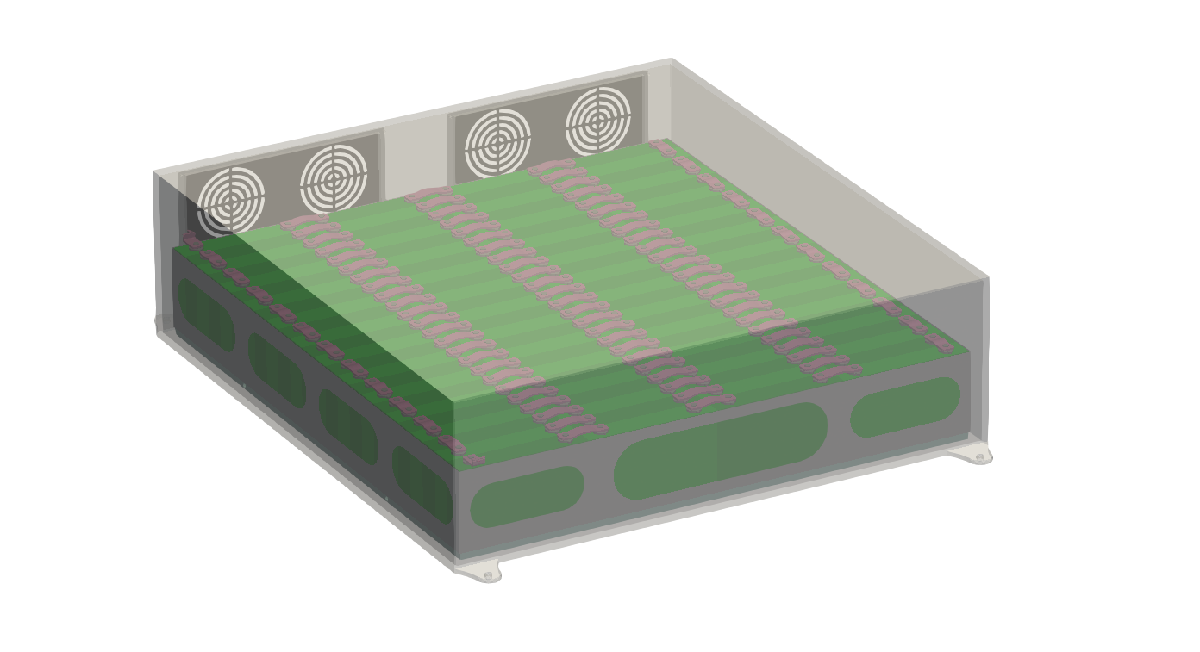

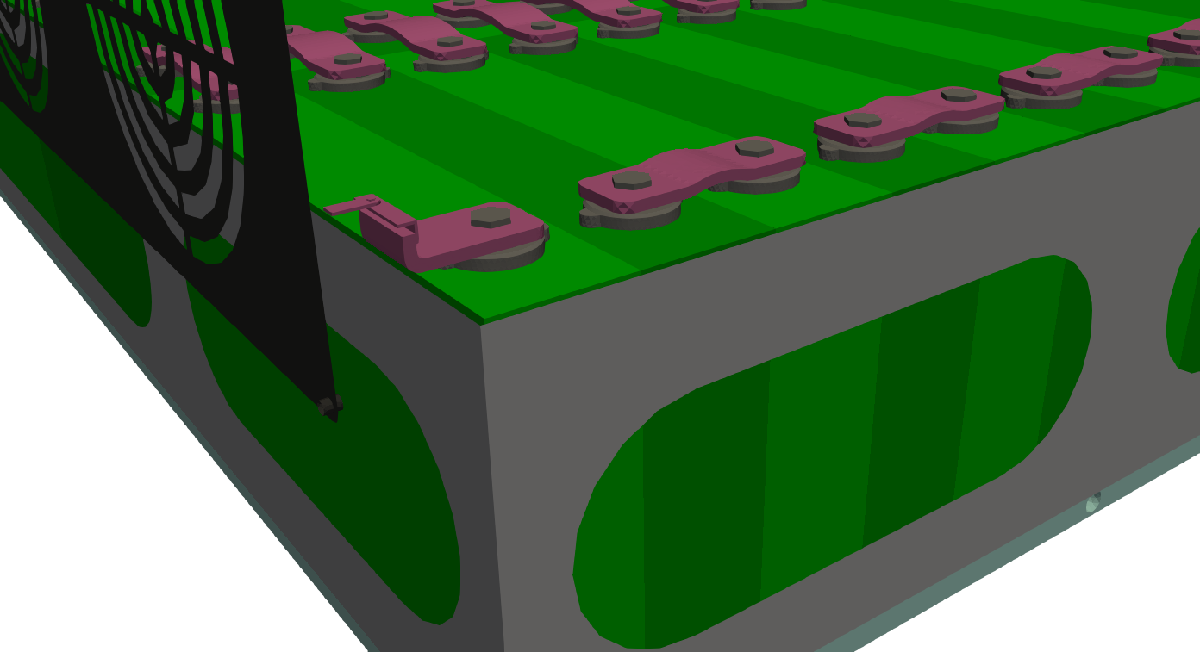

Our model imitates an electric car's battery pack and consists of 96 prismatic cells, connectors, terminals, holder, casing and 2 cooling plates. We have prepared the model as shown in the picture above. 

## Model preparation

Let's start with clearing your workspace, initialize enviorment and create empty model.

clc; clear; close all;

% Init Q-Bat
initQBatEnv();
model = createModel();

Firstly we have to create the cell prototype. We import proper mesh file and specify the material and electric properties of the cell, by appointing an Excel spreadsheet in which the data is collected and select type of cell circuit. Then, we create components and put the cells in our simulation domain.

%% Battery module definition
path = 'msh\';

model.addCellPrototype('proto_cell', 'mesh_path', [path 'cell_prism.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/cell_prism_linear_thermal_data.xlsx',...
    'electric_data', 'data\RC_linear_data.xlsx', 'circuit_type', 'RC');

cells_1 = model.createComponents('proto_cell', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0, 0, 0], 'n', [4, 24], ...
    'dist', [0.148,0.0265], 'component_name', 'cells_group1');

Next we define the cooling plate prototype. We have to define the pipe radius and material properties of the cooling plate and cooling fluid. Additionally, we define the pipe_discretization parameter to obtain a denser discretization of the pipe, due to its significant length and the pipe wall, inlet and outlet ids specified as function arguments. 


model.addCoolingPlatePrototype("proto_cooling_plate", ...
    'mesh_path', [path 'cooling_plate.msh'], 'scale_mesh', 0.001, ...
    'pipe_radius', 3e-3, ...
    'data', 'data/aluminium_linear_thermal_data.xlsx',...
    'coolant_data', 'data/coolant_linear_data.xlsx',...
    'number_of_modes', modes_number, ...
    'pipe_inlet_ids', [2169, 2171],'pipe_outlet_ids', [2150, 2176], ...
    'pipe_wall_ids', [77  76  75  74  73  72  71  70  69  68  67  66  65  64  63  62  61  60  59  58  57  56  55  54  53  52  51  50  49  48  47  46  45  44  43  42  41  40  39  38  37  36  35  34  33  32  31  30  29  28  27  26  25  24  23  22  21  20  19  18  17  16  15  14  13  12  11  10  9  8  7  6  5  4  3 2 1]',...
    'pipe_discretization', 250);

cooling_plate = model.createComponents('proto_cooling_plate', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0, 0, 0], 'n', [1, 2], ...
    'dist', [0, 0.318], 'component_name', 'cooling_plate');


Now we add the passive heat components prototypes. As before. we import proper mesh file, specify the material properties of each prototype by applying an Excel spreadsheet and create components.

model.addHeatComponentPrototype('comp_terminal_cell', 'mesh_path', [path 'cell_terminal_v2.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/aluminium_linear_thermal_data.xlsx', 'type', 'cylindrical', 'radius', 2.5e-3);
 
cell_terminal_1 = model.createComponents('comp_terminal_cell', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02, 0.01325, 0.091], 'n', [1, 23], ...
    'dist', [0.108, 0.0265], 'component_name', 'cell_terminal_1');

cell_terminal_2 = model.createComponents('comp_terminal_cell', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02+0.108, 0.01325, 0.091], 'n', [1, 24], ...
    'dist', [0.108, 0.0265], 'component_name', 'cell_terminal_2');

cell_terminal_end = model.createComponents('comp_terminal_cell', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02, 0.01325+23*0.0265, 0.091], 'n', [1, 1], ...
    'dist', [0.108, 0.0265], 'component_name', 'cell_terminal_end');

model.rotateAboutPoint(cell_terminal_end, [0.02, 0.01325+23*0.0265, 0.091], [0 0 pi])

cell_terminal_3 = model.createComponents('comp_terminal_cell', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02+0.148, 0.01325, 0.091], 'n', [2, 24], ...
    'dist', [0.108, 0.0265], 'component_name', 'cell_terminal_3');

cell_terminal_4 = model.createComponents('comp_terminal_cell', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02+2*0.148, 0.01325, 0.091], 'n', [2, 24], ...
    'dist', [0.108, 0.0265], 'component_name', 'cell_terminal_4');

cell_terminal_5 = model.createComponents('comp_terminal_cell', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02+3*0.148, 0.01325, 0.091], 'n', [2, 24], ...
    'dist', [0.108, 0.0265], 'component_name', 'cell_terminal_5');

model.addHeatComponentPrototype('comp_connector', 'mesh_path', [path 'connector.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/copper_linear_thermal_data.xlsx');

connector_1 = model.createComponents('comp_connector', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02, 3*0.01325, 0.094], 'n', [1, 11], ...
    'dist', [5*0.108+0.01325, 2*0.0265], 'component_name', 'connector_1');

connector_2 = model.createComponents('comp_connector', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02+3*0.148+0.108, 0.01325, 0.094], 'n', [1, 12], ...
    'dist', [0, 2*0.0265], 'component_name', 'connector_2');
 
model.addHeatComponentPrototype('proto_connector_rotated', 'mesh_path', [path 'connector_rotated.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/copper_linear_thermal_data.xlsx');

connector_rotated_1 = model.createComponents('proto_connector_rotated', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02+0.108, 0.01325, 0.094], 'n', [3, 24], ...
    'dist', [0.148, 0.0265], 'component_name', 'connector_rotated_1');

model.addHeatComponentPrototype('proto_connector_end', 'mesh_path', [path 'connector_end_v2.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/copper_linear_thermal_data.xlsx');
 
connector_end = model.createComponents('proto_connector_end', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02, 0.01325, 0.094], 'n', [1, 1], ...
    'dist', [0, 23*0.0265], 'component_name', 'connector_end');

connector_end_rotated = model.createComponents('proto_connector_end', 'type', 'pattern', ...
    'pattern_type', 'grid', 'start', [0.02, 0.01325, 0.094], 'n', [1, 1], ...
    'dist', [0, 23*0.0265], 'component_name', 'connector_end_rotated');

model.rotateAboutPoint(connector_end_rotated, [0.02, 0.01325, 0.094], [0 0 pi])

model.translate(connector_end_rotated, [0, 46*0.01325, 0]);

model.addHeatComponentPrototype('proto_holder', 'mesh_path', [path 'holder_shell.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/aluminium_linear_thermal_data.xlsx', 'shell', true, 'thickness', 0.003);

holder = model.createComponents('proto_holder', 'type','location', 'location_matrix', [0, 0, 0],...
    'component_name', 'holder');

% Casing definition
model.addHeatComponentPrototype('proto_casing_main', 'mesh_path', [path 'casing_main.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/ASA_linear_thermal_data.xlsx');
 
casing_main = model.createComponents('proto_casing_main', 'type','location', 'location_matrix', [0, 0, -0.008],...
    'component_name', 'casing_main');

model.addHeatComponentPrototype('proto_casing_vent', 'mesh_path', [path 'casing_vent_shell.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/ASA_linear_thermal_data.xlsx', 'shell', true, 'thickness', 0.003);
 
casing_vent = model.createComponents('proto_casing_vent', 'type','pattern', ...
    'pattern_type', 'grid', 'start', [0, 0, -0.008], 'n', [2, 1], ...
    'dist', [0.318807, 0], 'component_name', 'casing_vent');

Finally we can create our battery module with casing by simply defining new assembly. Add contacts between the components and specify the conductivity of the contacts and the thickness. We also measure the assembly times time by using tic and toc functions.

%% Assemblies

tic;

model.createAssembly('battery_module_1', ["cells.*","cells.*","cooling_plate.*"],...
     'create_all_contacts', true,...
     'contact_thickness', 1e-3, 'contact_conductivity', 10, ...
     'number_of_max_contact_modes', 1, 'basis_type', 'eigs','search_for_cylindrical_contacts', false);
  
model.createAssembly('battery_module_2', ["battery_module_1", "holder.*"],...
     'create_all_contacts', true,...
     'contact_thickness', 1e-3, 'contact_conductivity', 1, ...
     'number_of_max_contact_modes', 1, 'basis_type', 'eigs','search_for_cylindrical_contacts', false);
 
model.createAssembly('battery_module_3', ["connector.*", "cell_terminal.*"],...
     'create_all_contacts', true,...
     'contact_thickness', 1e-3, 'contact_conductivity', 100, ...
     'number_of_max_contact_modes', 1, 'basis_type', 'eigs','search_for_cylindrical_contacts', true);
 
model.createAssembly('battery_module_4', ["battery_module_3","battery_module_2"],...
     'create_all_contacts', true,...
     'contact_thickness', 1e-3, 'contact_conductivity', 100, ...
     'number_of_max_contact_modes', 1, 'basis_type', 'eigs','search_for_cylindrical_contacts', false);

model.createAssembly('casing_1', ["casing_main.*", "casing_vent.*"],...
     'create_all_contacts', true,...
     'contact_thickness', 1e-3, 'contact_conductivity', 1e-1, ...
     'number_of_max_contact_modes', 1, 'basis_type', 'eigs','search_for_cylindrical_contacts', false);
 
model.createAssembly('battery_pack', ["casing_1", "battery_module_4"],...
     'create_all_contacts', true,...
     'contact_thickness', 1e-3, 'contact_conductivity', 1e-1, ...
     'number_of_max_contact_modes', 10, 'basis_type', 'eigs','search_for_cylindrical_contacts', false);

assembly_time = toc;

Then, we create electric circuit from previously defined cell components.

%% Electro circuit
cell_name = string(zeros(24, 4));

for i = 1:24
    x = i;
    for j = 1:4
             
        cell_name(i,j) = sprintf("cells_group1_%d",x); 
        x=x+24;
     
    end
    
    if mod(i,2) == 0
        cell_name(i,:) = flip(cell_name(i,:));
        
    end

end

cell_name_electro = reshape(cell_name',1,[]);

model.createElectricCircuit("ele_circ", [cell_name_electro], "96s1p");

We set the boundary condition (mass flow of coolant in pipes and temperature) and the initial conditions (temperature in degrees Celsius). We will add to the model the air, which will be modeled as a finite volume body. The contact surface ids of cells, cooling plates and housing were found using displayPrototypes functions. We will also assign Robin boundary condition to the housing outer boundaries.

%% IC and BC

% Add Air
model.addAir("air", 'data', 'data/air_linear_data.xlsx',...
    'dimensions', [700e-3, 700-3, 500e-3],...
    'starting_point', [-0.02, -0.02, -0.02], ...
    'air_contact_bodies',...
    ["cells.*", "holder.*", "casing_main.*"], ...
    'air_contact_surf_ids',...
    [repmat({[5]}, 1, 96),...
    {[1, 2, 3, 4]},...
    {[44, 43, 45, 46, 60]}], ...
    'air_contact_alpha', 10, 'n_partitions', [10, 10, 10]);

model.setIC('.*', 'T', 18);
model.setIC('cooling_plate_1', 'mass_flow', 0.01, 'T', 15);
model.setIC('cooling_plate_2', 'mass_flow', 0.01, 'T', 15);

model.addBC("cooling_plate_1", [],'type', 'PipeValue', 'T', 15);
model.addBC("cooling_plate_1", [],'type', 'PipeMassFlow', 'mass_flow', 0.01);
model.addBC("cooling_plate_2", [],'type', 'PipeValue', 'T', 15);
model.addBC("cooling_plate_2", [],'type', 'PipeMassFlow', 'mass_flow', 0.01);

model.addBC("casing_main.*", [21, 20, 19, 18, 59, 13], 'type', 'Robin', ...
'alpha', 20, 'T_inf', 18);

model.addBC("casing_vent.*", [1], 'type', 'Robin', ...
'alpha', 20, 'T_inf', 18);

## Simulation run

Now it is time to prepare our model for simulation. Q-Bat is based on the Reduced Order Modeling approach and requires an additional step of model assemblation and reduction but allows to perform simulation substantially faster. If you have access to MATLAB's parallel toolbox you can uncomment the first line of code and additionally decrease simulation time by allowing parallel computing.

%% Model Preparation and run
prep_time = tic;
% model.flag_is_parallel = true;
model_struct = model.prepare();
prep_time = toc(prep_time);

We define the current profile by applying an Excel spreadsheet and assign the loaded profile to our cells.

current = readtable("Webinar/data/current.xlsx");
current.Properties.VariableNames = {'t','current'};
model_struct.ele_circ_electro = current;

 Once the model is compiled we can run the simulation. As the first parameter we specify the time step in seconds, next the number of time steps we want to simulate and number of time steps of the electrical calculation.

tic;
model.run(10, 180, 'electroSubsteps', 100, 'signals_data', model_struct,...
    'solver', 'Direct')
run_time = toc;


## Postprocessing

Now using different post processing functions, we can plot the temperatures in chosen bodies, the outlet temperature of the cooling fluid or electrical parameters like current over time and State of charge.

% Thermal

model.plotMaxTempOverTime("cells.*")
model.plotMinTempOverTime("cells.*")
model.plotMeanTempOverTime("cells.*")

model.plotCoolantOutletTempOverTime("cooling.*")

% Elctric

model.plotCircuitVoltage("ele_circ")
model.plotSOCOverTime()
model.plotCurrentOverTime()

We can also plot the solution for the battery pack for a selected time step.

model.plotSolution("battery_module_4", 180)

Lastly, we can save the results and export our solution to extensions which are compatible with other software.

model.saveModel("battery_pack_96S1P_results");
model.exportSolutionToCGNS("battery_pack", "battery_pack_96S1P.cgns");

## Mesh sensitivity study

In this case, it is shown how to check for a mesh independent solution. We prepared three meshes with the different numbers of elements. 

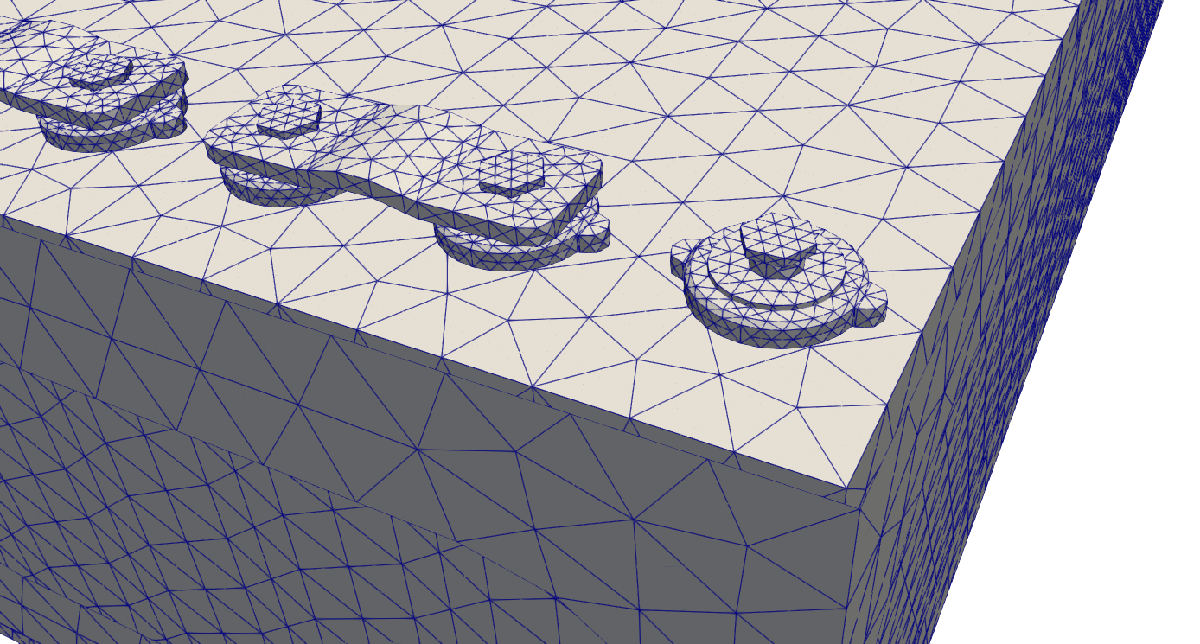 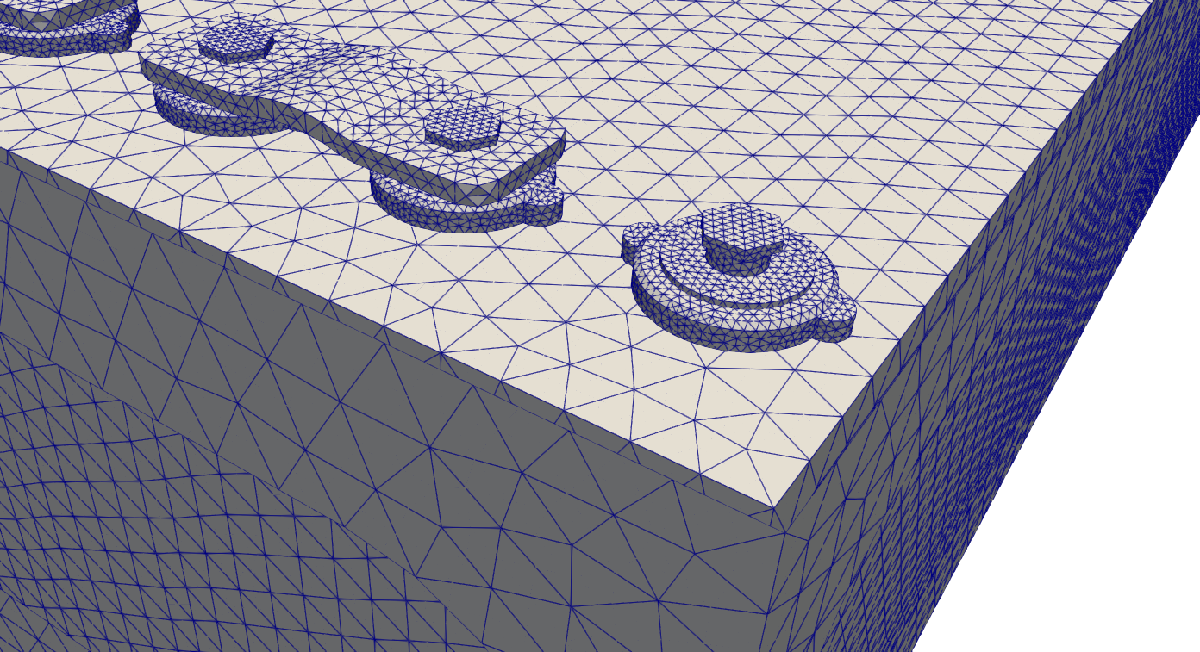     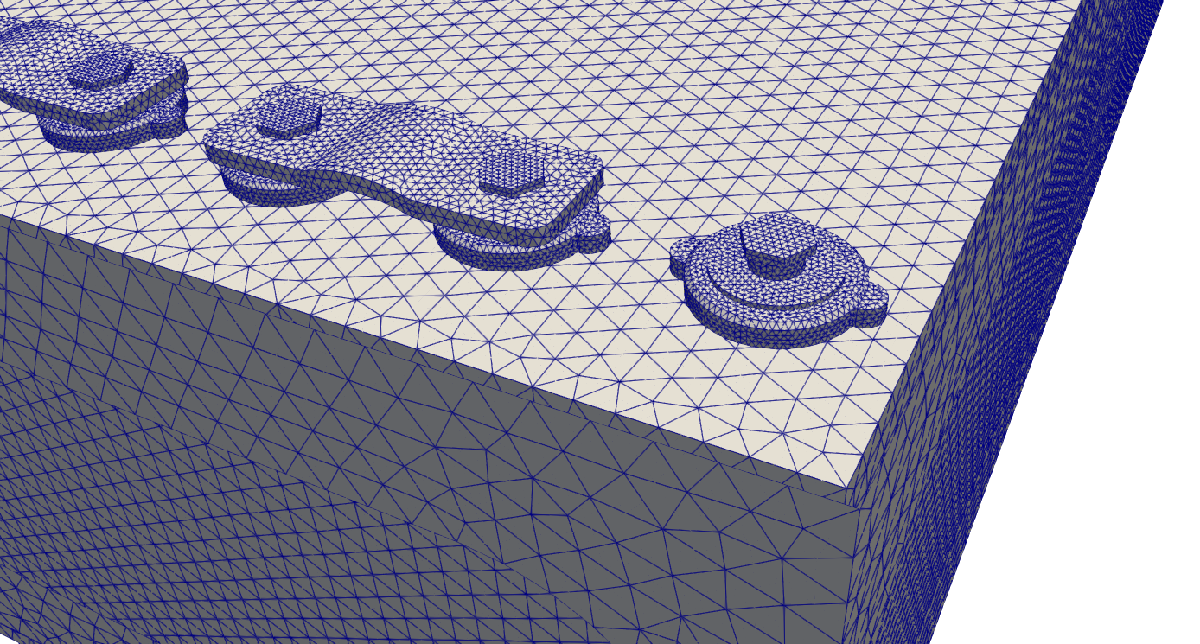

We change the path to proper mesh file by changing variable *path* in the beginning of the script and run simulation again.

path = 'msh_coarse\';

model.addCellPrototype('proto_cell', 'mesh_path', [path 'cell_prism.msh'], 'scale_mesh', 0.001, ...
    'data', 'data/cell_prism_linear_thermal_data.xlsx',...
    'number_of_modes', modes_number, ...
    'electric_data', 'data\RC_linear_data.xlsx', 'circuit_type', 'RC');